# The Bisection Method

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Calculate inital values for variables

Create brackets

xp = -0.5;
xn = 0.8;

Calculate the midpoint

xmp = (xn + xp)/2;

Calculate 

ymp = 0.5 - sin(xmp) - xmp.^2;

## Define the Bisection Method

In the previous activity, this rule was established to update the brackets:

If *y**m**p* is less than 0, then *x**n**e**g*=*x**m**p*.

If *y**m**p* is greater than 0, then *x**p**o**s*=*x**m**p*.

The rule can be implemented as an `if`/`else` statement in MATLAB.

For any value of `n`, you can repeat code `n` times using a `for` loop.

`for` `i` `=` `1``:``n`

`% Do something`

`end`

The script repeats the bisection method using a `for` loop, and the value chosen for `n` in the `for` loop determines the accuracy of the root.

for iteration = 1:10
    if ymp < 0
        % ymp is less than zero
        xn = xmp;
    else
        % ymp is greater than zero
        xp = xmp;
    end
    xmp = (xn + xp) / 2;
    ymp = 0.5 - sin(xmp) - xmp.^2;
end

## Display the root value

xmp

xmp = 0.3703

ymp

ymp = 0.0010

Plot the function and the root

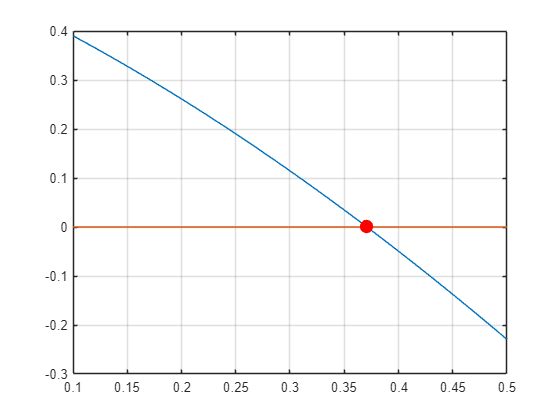

xvals = linspace(0.1,0.5);
yvals = 0.5 - sin(xvals) - xvals.^2;
plot(xvals,yvals)
hold on
plot([0.1 0.5],[0 0])
plot(xmp,ymp,"r.","MarkerSize",30)
hold off
grid on